# Pizza3 - WORKSHOP - PostTreatment - Part 1

INRAE\Han Chen, Olivier Vitrac - rev. 2023-08-25, 2023-09-06

## Synopsis

The workshop is organized into two interconnected parts to demonstrate how spatial and temporal information can be reconstructed from the dynamics of multi-particle systems, as utilized in Pizza3. The workshop focuses on managing large data files generated from MD-like simulations that contain atomistic information such as positions, velocities, forces, and more. Through specific post-treatment, these details are converted into meaningful time or spatial averages or fluctuating quantities.

#### Part 1: Temporal Information Extraction

Objective: To extract temporal information from large dump files (5-100 GB) generated by LAMMPS that are beyond the processing capacity of conventional computers.

Applied Physics: The section emphasizes simple physical concepts, aiming to illustrate how scalar quantities can be retrieved and plotted with low computational cost.

Key Learnings:

- Preprocessing of large files.

- Analysis of temporal evolution for selected particles.

- Study of solid obstacle dynamics (including position and movement, shape deformation, and moment of inertia analysis).

#### Part 2: Spatial Reconstruction and Field Analysis

Objective: Utilizing the results from Part 1, this section aims to reconstruct various fields (velocity, stresses) through the definitions of underlying physics and kernel interpolation.

Key Learnings:

- First description of fluid-solid interactions.

- Visualization techniques.

- Overview of possible extensions.

Overall, the workshop provides hands-on experience and detailed understanding of translating complex particle dynamics into meaningful physical insights, with an emphasis on efficient computational methodologies.

## Description and dependencies


% WORKSHOP built on Billy production file (suspended particle in a fluid)
% This example takes the benefit of a Lagrangian description

% INRAE\Olivier Vitrac, Han Chen - rev. 2023-08-22

% MATLAB FILES included in this distribution (either from INRAE/MS or Pizza3 project)

% Main file
% ├── example1.m
% ├── notebook
% │  ├── example1.mlx <-- this file

% Main features demonstrated
% ├── lamdumpread2.m     ==> the Swiss knife for the manipulating HUGE dump files (version 2 as it is the fork for Pizza3)
% ├── buildVerletList.m  --> the basic tool for statistical physics, it implement an efficient grid search method

% Other dependencies and future workshop extensions (from Pizza3)
% ├── checkfiles.m
% ├── forceHertzAB.m
% ├── forceHertz.m
% ├── forceLandshoff.m
% ├── interp2SPH.m
% ├── interp3SPH.m
% ├── interp3SPHVerlet.m
% ├── kernelSPH.m
% ├── KE_t.m
% ├── packing.m
% ├── packing_WJbranch.m
% ├── packSPH.m
% ├── particle_flux.m
% ├── partitionVerletList.m
% ├── selfVerletList.m
% ├── updateVerletList.m
% └── wallstress.m

% Dependencies from MS (INRAE/Molecular Studio) 
% ├── color_line3.m
% ├── dispb.m
% ├── dispf.m
% ├── explore.m
% ├── fileinfo.m
% ├── lastdir.m
% ├── MDunidrnd.m
% ├── plot3D.m
% ├── rootdir.m

% DUMP FILES included in this workshop
% ├── dumps
% │  └── hertz
% │  ├── dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle             <== it is the original dump file
% │  └── PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle    <-- the split folder
% │  ├── TIMESTEP_000000000.mat                                                                   <-- a split file
% │  ├── TIMESTEP_000050000.mat                                                                   <-- 158 splits (frames)
% │  ├── TIMESTEP_000100000.mat                                                                   <-- the value represent time
%             ...

## STEP 1 - PREPROCESSING

Preprocess all the dumps (no need to precise the filenames, only the pattern).

Lamdumpread2 include() two PREPROCESSORS 'prefetch' and 'split'.

### 2D simulations

-  prefetch should be preferred for 2D files (relatively smaller number of particles and many time frames) 

- Usage: `lamdumpread2('dump.*','prefetch');`

### 3D simulations

- split should be preferred for large 3D files (large number of particles and a relatively smaller number of time frames)

- Usage: `lamdumpread2('dump.*','split');`

Note: this step should be used ONLY once, applying again will overwrite the previous splits (frames)

warning off
PREPROCESS_FLAG = true; % set it to true to preprocess your data
addpath(rootdir(pwd),'-begin')
if PREPROCESS_FLAG
    datafolder = '../dumps/';
    lamdumpread2(fullfile(datafolder,'dump.*'),'split'); % for large 3D
end

LAMPDUMPREAD AUTO 1 of 1
LAMMPS DUMP file...
	dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle		10-Mar-2023 15:35:03		9829.7 MBytes		./dumps/hertz
[157:8450000] spl[last=8500000] 158 split files completed in 312 s
 in	./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle



ans = struct with fields:
           TIME: 17
       TIMESTEP: 8500000
         NUMBER: 313344
            BOX: [3×2 single]
          ATOMS: [313344×37 single]
    description: [1×1 struct]
            nfo: [1×1 struct]


## STEP 2 - PROCESS SPECIFICALLY ONE FILE

we do work with one dump file

datafolder = './dumps/';
dumpfile = 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle';
datafolder = lamdumpread2(fullfile(datafolder,dumpfile),'search'); % fix datafolder based on initial guess

Look for 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle'... (be patient)
The dumpfile 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle' has been found with the method 'splitfolder'
	in the folder: ./dumps/hertz
the original search started in ./dumps
The frame (split) folder is: ./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
The first frame (split) is located in: ./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle/TIMESTEP_000000000.mat
The prefetch is split in several files.
158 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 05	  Column 06	  Column 07	  Column 08	  Column 09	  Column 10	
        0	   800000	  1600000	  2400000	  3200000	  4650000	  5450000	  6250000	  7050000	  7850000	
    50000	   850000	  1650000	  2450000	  3250000	  4700000	  5500000	  6300000	  7100000	  7

defaultfiles = lamdumpread2(fullfile(datafolder,dumpfile),'default'); % default folder (just for check)

Here, `datafolder` is set to the path containing the dump files, and `dumpfile` specifies the particular file to process.

The functions `lamdumpread2` with 'search' and 'default' flags are used to fix the data folder based on an initial guess and set default parameters, respectively.

## Extract the types of atoms and the list of available frames

This step extracts essential information from the dump file, such as the types of atoms and the list of available frames, utilizing the `lamdumpread2` function.

X0 = lamdumpread2(fullfile(datafolder,dumpfile)); % default frame

The prefetch is split in several files.
158 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 05	  Column 06	  Column 07	  Column 08	  Column 09	  Column 10	
        0	   800000	  1600000	  2400000	  3200000	  4650000	  5450000	  6250000	  7050000	  7850000	
    50000	   850000	  1650000	  2450000	  3250000	  4700000	  5500000	  6300000	  7100000	  7900000	
   100000	   900000	  1700000	  2500000	  3300000	  4750000	  5550000	  6350000	  7150000	  7950000	
   150000	   950000	  1750000	  2550000	  3350000	  4800000	  5600000	  6400000	  7200000	  8000000	
   200000	  1000000	  1800000	  2600000	  3400000	  4850000	  5650000	  6450000	  7250000	  8050000	
   250000	  1050000	  1850000	  2650000	  3450000	  4900000	  5700000	  6500000	  7300000	  8100000	
   300000	  1100000	  1900000	  2700000	  4150000	  4950000	  5750000	  6550000	  7350000	  8150000	
   350000	  1150000	  1950000	  2750000	  4200000	  5000000	  5800000	  6600000	  7400000	  8200000	
   

natoms = X0.NUMBER;
timesteps = X0.TIMESTEPS;
atomtypes = unique(X0.ATOMS.type);
ntimesteps = length(timesteps);


- `X0`: Represents the default frame.

- `natoms`: Contains the total number of atoms.

- `timesteps`: Provides the list of available time steps.

- `atomtypes`: Holds the unique types of atoms.

- `ntimesteps`: Contains the total number of time steps.This step is crucial for understanding the data's structure and providing insights into the atom types and available frames.

## Extract the middle frame (i.e. in the middle of the simulation duration)

This step concentrates on extracting the middle frame of the simulation duration. The default frame `X0` might be too far from the steady state for advanced analysis, so the middle frame is specifically targeted.

Xmiddle = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps(ceil(ntimesteps/2))); % middle frame

Use the prefetch (split: TIMESTEP 4550000) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_004550000.mat		01-Sep-2023 15:56:29		9.0 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.337 s


- `Xmiddle`: Represents the middle frame of the simulation, which is extracted using the `lamdumpread2` function with the `usesplit` flag.

## Extract the number of beads for each type

In this step, the number of beads for each atom type is extracted. The most populated type is assumed to be the fluid, while the least populated type is assumed to be the particle.

T = X0.ATOMS.type;
natomspertype = arrayfun(@(t) length(find(T==t)),atomtypes);
[~,fluidtype] = max(natomspertype);
[~,solidtype] = min(natomspertype);
walltypes = setdiff(atomtypes,[fluidtype,solidtype]);

- `T`: Represents the types of atoms from the default frame.

- `natomspertype`: An array that contains the number of atoms for each type.

- `fluidtype`: Identifies the type corresponding to the fluid (the most populated).

- `solidtype`: Identifies the type corresponding to the particle (the least populated).

- `walltypes`: Contains the types other than fluid and solid.

This step assists in classifying the types of beads in the system and understanding their distribution, crucial for further analyses and simulations.

## Estimate the fluid bead size

This step aims to estimate the size of the fluid bead. The calculation starts with an initial guess based on the assumption that the bead is cubic to estimate the cutoff, followed by a more refined estimation using the `buildVerletList()` function.

fluidxyz = X0.ATOMS{T==fluidtype,{'x','y','z'}};
fluidid = X0.ATOMS{T==fluidtype,'id'};
nfluidatoms = length(fluidid);
nsolidatoms = natomspertype(solidtype);
% first estimate assuming that the bead is a cube
boxdims = X0.BOX(:,2) - X0.BOX(:,1);
Vbead_guess = prod(boxdims)/natoms;
rbead_guess = (3/(4*pi)*Vbead_guess)^(1/3);
cutoff = 3*rbead_guess;
[verletList,cutoff,dmin,config,dist] = buildVerletList(fluidxyz,cutoff);

Build Verlet list by searching in blocks...
... done in 0.3793 s with 729 search blocks | minimum distance 2.083e-05
	 Sort the Verlet list...
	 ... done in 0.515 s
buildVerletList: all done in 24.9 s for 215025 atoms


rbead = dmin/2;

- `fluidxyz`: Coordinates of the fluid atoms.

- `fluidid`: IDs of the fluid atoms.

- `nfluidatoms`: Number of fluid atoms.

- `nsolidatoms`: Number of solid atoms (calculated based on the previously identified solid type).

- `rbead_guess`: Initial guess of bead radius.

- `cutoff`: Cutoff distance for the Verlet list.

- `rbead`: Final estimated bead radius.

The process estimates bead size using a specific tool (`buildVerletList`) designed to work with the physical arrangement of the beads. The accurate bead size is essential for subsequent calculations involving fluid dynamics and interactions.

## **STEP 7 - FINDING THE FLOW DIRECTION**

This step is crucial for identifying the primary flow direction within the system. The main idea is to determine the largest dimension of the bounding box and assume that the fluid flows along this axis. 

[~,iflow] = max(boxdims);
iothers = setdiff(1:size(X0.BOX,1),iflow);

- `fluidxyz`: Coordinates of the fluid atoms.

- `fluidid`: IDs of the fluid atoms.

- `nfluidatoms`: Number of fluid atoms.

- `nsolidatoms`: Number of solid atoms (calculated based on the previously identified solid type).

- `rbead_guess`: Initial guess of bead radius.

- `cutoff`: Cutoff distance for the Verlet list.

- `rbead`: Final estimated bead radius.

The process estimates bead size using a specific tool (`buildVerletList`) designed to work with the physical arrangement of the beads. The accurate bead size is essential for subsequent calculations involving fluid dynamics and interactions.

## **STEP 8 - SEPARATING TOP AND BOTTOM WALLS**

In this simulation, two walls are present, and they move in opposite directions. This step serves to identify and separate the top and bottom walls based on their directional movement. 

vel = {'vx','vy','vz'};
wall1vel = Xmiddle.ATOMS{Xmiddle.ATOMS.type==walltypes(1),vel{iflow}}; wall1vel = wall1vel(1);
wall2vel = Xmiddle.ATOMS{Xmiddle.ATOMS.type==walltypes(2),vel{iflow}}; wall2vel = wall2vel(1);
[wallvel,iwall] = sort([wall1vel,wall2vel],'descend'); % 1 is top (>0), 2 is bottom;
walltypes = walltypes(iwall);

- `wall1vel` and `wall2vel`: Velocities of the first and second walls along the main flow direction (identified in STEP 7).

- The top wall's velocity is expected to be positive, and the bottom wall's velocity is expected to be negative.

## **STEP 9 - LOCATING THE PARTICLE (OBSTACLE) POSITION WITHIN THE FLOW**

In this step, the position of the solid "BIG" particle (referred to as an "obstacle") within the flow is determined. 

solidxyz = Xmiddle.ATOMS{T==solidtype,{'x','y','z'}};
solidid = Xmiddle.ATOMS{T==solidtype,'id'};
solidbox = [min(solidxyz);max(solidxyz)]';

- `solidxyz` stores the spatial coordinates of the particle, and `solidid` stores its unique identifier.

- The `solidbox` variable captures the bounding coordinates, which might be used to represent or analyze the particle's extent or confinement within the flow

## STEP 10 - PICKING N PARTICLES RANDOMLY FROM THE LEFT INLET AND INCLUDED IN THE MASK OF THE SOLID (INITIAL FRAME)

In this step, a specific number of particles (n = 300) are randomly selected from the left inlet of the system and included within the mask of the solid structure. This selection helps simulate the initiation of flow and the behavior of the particles as they approach and interact with the solid structure.

- Defining the Selection Parameters:

n = 300;
tol = 0.5; % add 40% particles around
selectionbox = NaN(3,2);
selectionbox(iflow,:) = [X0.BOX(iflow,1), X0.BOX(iflow,1)+2*rbead];
selectionbox(iothers,:) =  (1+tol)*(solidbox(iothers,2)-solidbox(iothers,1))*[-1 1]/2 ...
    + (solidbox(iothers,1)+solidbox(iothers,2)) * [1 1]/2;
ok = true(nfluidatoms,1);
for c = 1:3
    ok = ok & (fluidxyz(:,c)>=selectionbox(c,1)) & (fluidxyz(:,c)<=selectionbox(c,2));
end
icandidates = find(ok);
iselected = icandidates(MDunidrnd(length(icandidates),n));
selectedid = fluidid(iselected); % ID to be used

This portion of code locates the fluid particles within the selection box and picks `n` of them randomly.

- Visualization:

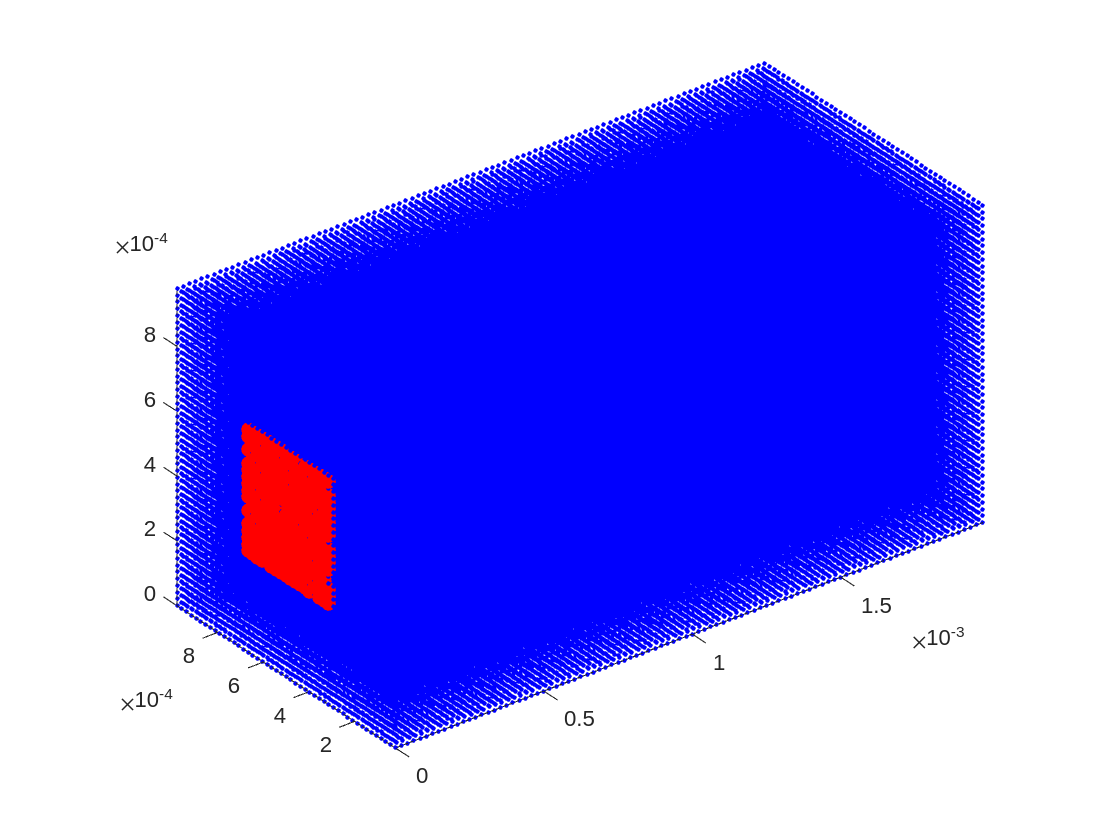

% plot selected particles and other ones
figure, hold on
plot3D(fluidxyz,'b.')
plot3D(fluidxyz(iselected,:),'ro','markerfacecolor','r')
plot3D(solidxyz,'ks','markerfacecolor','k')
view(3), axis equal

The code also provides a 3D visualization of the selected particles, allowing for an intuitive understanding of their initial placement and relationship to the solid structure.

## STEP 11 - GENERATE THE TRAJECTORY FOR THE SELECTED PARTICLES (FOR ALL FRAMES)

The trajectories are determined across all frames of the simulation, providing a clear understanding of how the selected particles move and interact over time.

Xselection = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps,selectedid);

Use the prefetch (split: TIMESTEP 0) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		01-Sep-2023 15:53:57		1.0 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 50000) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000050000.mat		01-Sep-2023 15:53:59		6.1 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 100000) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000100000.mat		01-Sep-2023 15:54:01		7.2 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMEST

Here, the function `lamdumpread2` is called with specific parameters to load the data pertaining to the selected particles' trajectories:

- `fullfile(datafolder,dumpfile)`: Specifies the location of the file containing the dump data.

- `'usesplit'`: An option indicating that each split (subdivision of data) is loaded individually.

- `timesteps`: Represents the time steps in the simulation for which the trajectories are to be generated.

- `selectedid`: The IDs of the selected particles whose trajectories are to be generated.

By specifying these parameters, the function reads only the required data for the selected particles, thus optimizing the process.

## STEP 12 - COLLECT THE TRAJECTORY OF THE SOLID PARTICLE FOR ALL FRAMES

This step involves the collection of the trajectory data for the solid obstacle (or particles, if there are multiple solid particles being considered) throughout the entire simulation. It provides a continuous record of the solid particle's position and motion, allowing for a detailed analysis of its behavior.

- Command to Retrieve the Trajectory of Solid Particles Consiting in The Obstacle:

Xsolid = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps,solidid);

Use the prefetch (split: TIMESTEP 0) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		01-Sep-2023 15:53:57		1.0 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 50000) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000050000.mat		01-Sep-2023 15:53:59		6.1 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 100000) folder (instead of './dumps/hertz/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000100000.mat		01-Sep-2023 15:54:01		7.2 MBytes		./dumps/hertz/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMEST

- `fullfile(datafolder,dumpfile)`: Specifies the path to the dump file containing the simulation data.

- `'usesplit'`: A parameter indicating that each split is loaded individually, enhancing efficiency.

- `timesteps`: Specifies the time steps in the simulation for which the solid particle's trajectory is to be extracted.

- `solidid`: The ID or IDs of the solid particle(s) whose trajectory is being retrieved.

## STEP 13 - STORE THE TRAJECTORIES IN AN $ntimesteps\times 3\times n$ MATRIX

This step entails storing the trajectories of the selected fluid and solid particles in a structured matrix. Incomplete frames, a common occurrence in LAMMPS, are handled, and missing data are kept as NaN (Not a Number).

**Initialization of Variables:**

- Trajectories and velocities of selected fluid particles: `seltraj` and `selveloc`.

- Trajectory of solid particles: `solidtraj`.

- A boolean variable to indicate good frames: `goodframes`.

**Looping through Time Steps:The loop iterates through each time step, handling fluid and solid atoms separately:**

Fluid Atoms:

- Reading the frame for selected fluid atoms.

- If the frame is incomplete (missing atoms), a warning is displayed, and the available data are stored at the corresponding indices. The missing data are kept as NaN.

- If the frame is complete, the trajectory and velocity data are stored.

Solid Atoms:

- Reading the frame for solid atoms.

- Similar to the fluid atoms, the trajectory data are stored, handling incomplete frames if necessary.

Velocity Magnitude Calculation:

- The magnitude of the velocity for the fluid particles is computed and stored.

Interpretation of Solid Deformation:

- Solid deformation is interpreted through calculations involving moments of inertia $ I_{xx}, I_{yy}, I_{zz}$ and Tailor deformation $D$.

- Centered solid trajectory is computed using `centeredsolidtraj`.

[seltraj,selveloc] = deal(NaN(ntimesteps,3,n,'single'));
solidtraj = NaN(ntimesteps,3,nsolidatoms,'double');
goodframes = true(ntimesteps,1);
for it = 1:ntimesteps
    % read fluid atoms
    selframe = Xselection.ATOMS(Xselection.ATOMS{:,'TIMESTEP'} == timesteps(it),:);
    nfoundatoms = size(selframe,1);
    if nfoundatoms<n % incomplete dumped frame (it may happen in LAMMPS)
        dispf('incomplete frame %d/%d (t=%0.4g): %d of %d fluid atoms missing',it,ntimesteps,timesteps(it),n-nfoundatoms,n)
        [~,iatoms,jatoms] = intersect(selectedid,selframe.id,'stable');
        seltraj(it,:,iatoms) = permute(selframe{jatoms,{'x','y','z'}},[3 2 1]);
        goodframes(it) = false;
    else
        seltraj(it,:,:) = permute(selframe{:,{'x','y','z'}},[3 2 1]);
        selveloc(it,:,:) = permute(selframe{:,{'vx','vy','vz'}},[3 2 1]);
    end
    % read solid atoms
    solidframe = Xsolid.ATOMS(Xsolid.ATOMS{:,'TIMESTEP'} == timesteps(it),:);
    nfoundatoms = size(solidframe,1);
    if nfoundatoms<nsolidatoms % incomplete dumped frame (it may happen in LAMMPS)
        dispf('incomplete frame %d/%d (t=%0.4g): %d of %d solid atoms missing',it,ntimesteps,timesteps(it),nsolidatoms-nfoundatoms,nsolidatoms)
        [~,iatoms,jatoms] = intersect(solidid,solidframe.id,'stable');
        solidtraj(it,:,iatoms) = permute(solidframe{jatoms,{'x','y','z'}},[3 2 1]);
        goodframes(it) = false;
    else
        solidtraj(it,:,:) = permute(solidframe{:,{'x','y','z'}},[3 2 1]);
    end
end

incomplete frame 67/158 (t=3.3e+06): 32 of 300 fluid atoms missing


incomplete frame 67/158 (t=3.3e+06): 546 of 1551 solid atoms missing


incomplete frame 70/158 (t=3.45e+06): 25 of 300 fluid atoms missing


incomplete frame 70/158 (t=3.45e+06): 299 of 1551 solid atoms missing


% velocity magnitude for the fluid particles
selveloc_magnitude = squeeze(sqrt(sum(selveloc.^2, 2)));

% Interpertation of the solid deformation via Ixx, Iyy, Izz and D
centeredsolidtraj = solidtraj - repmat(nanmean(solidtraj,3),1,1,nsolidatoms);

Comments:

- By storing the trajectory information in structured matrices, subsequent analysis, visualization, and interpretation become more efficient and coherent.

- Handling incomplete frames ensures that the analysis can proceed without disruption, providing as much information as possible despite the missing data.

- Code Segment:The given code segment meticulously details how to perform these operations, using loops to iterate through time steps, conditional statements to handle incomplete frames, and mathematical operations to compute relevant quantities.

## STEP 14 - CALCULATE THE APPROXIMATE MAJOR AND MINOR AXES (ASSUMING AN ELLIPSOIDAL SHAPE)

This step is centered around building the inertia tensor and calculating the approximate major and minor axes of the solid particle, assuming an ellipsoidal shape. It also calculates the Taylor deformation over time.

**Initialization of Moments of Inertia:**

- Three variables `Ixx`, `Iyy`, and `Izz` are initialized to store the principal moments of inertia for each time step.

- Loop through Time Steps:The process iterates through each time step, performing the following:

**Extraction of Coordinates:**

- The centered solid trajectory for the current time step is extracted into a matrix `coordinates`.

- Computation of the Covariance Matrix:

- A covariance matrix `C` is calculated by multiplying `coordinates` with its transpose and normalizing by the number of solid atoms.

**Singular Value Decomposition (SVD):**

- SVD is performed on the covariance matrix, resulting in matrices `U` and `S`.

- Storage of Principal Moments of Inertia:

- The principal moments of inertia are extracted from the diagonal of `S` and stored in `Ixx`, `Iyy`, and `Izz`.

**Approximation of Major and Minor Axes:**

- The major (`L`) and minor (`B`) axes are calculated using the principal moments of inertia, assuming an ellipsoidal shape for the solid particle.

- Calculation of the Taylor Deformation:

- The Taylor deformation `D` is calculated using the major and minor axes.

% Building the inertia tensor

% Initialize moments of inertia
Ixx = zeros(ntimesteps, 1);
Iyy = zeros(ntimesteps, 1);
Izz = zeros(ntimesteps, 1);

for it = 1:ntimesteps
    % Extract the 3 x natoms matrix for the current timestep
    coordinates = squeeze(centeredsolidtraj(it, :, :))';
    
    % Compute the covariance matrix
    C = coordinates' * coordinates / nsolidatoms;
    
    % Perform Singular Value Decomposition
    [U, S, ~] = svd(C);
    
    % The principal moments of inertia are on the diagonal of S
    Ixx(it) = S(1, 1);
    Iyy(it) = S(2, 2);
    Izz(it) = S(3, 3);
end
% Calculate the approximate major and minor axes (assuming an ellipsoidal shape)
L = sqrt(5 * (Ixx + Iyy - Izz) / 2); % Major axis (approximation)
B = sqrt(5 * (Ixx - Iyy + Izz) / 2); % Minor axis (approximation)
% Calculate the Taylor deformation 
D = (L - B) ./ (L + B);

Plotting Taylor Deformation Over Time:

- A plot is generated to visualize the Taylor deformation over time, providing insights into the deformation behavior of the solid particle.

- Significance:

- The calculated major and minor axes provide valuable geometric insights into the solid particle's shape.

- The Taylor deformation offers a quantitative measure of deformation, which may be crucial for understanding fluid-solid interactions and material properties.

Significance:

- The calculated major and minor axes provide valuable geometric insights into the solid particle's shape.

- The Taylor deformation offers a quantitative measure of deformation, which may be crucial for understanding fluid-solid interactions and material properties.

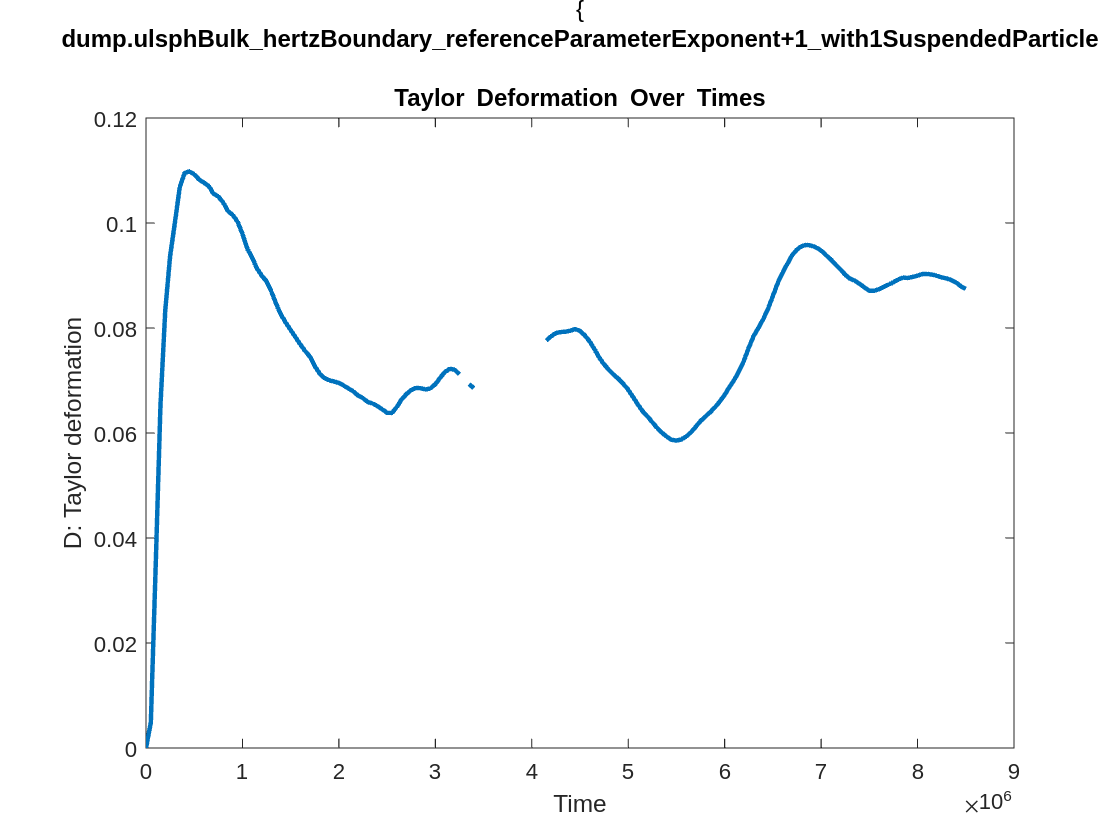

figure;
plot(timesteps, D,'-','linewidth',2);
xlabel('Time'); ylabel('D: Taylor deformation');
title({'\rm{' strrep(dumpfile, '_', '\_') '}:' '\bf{Taylor Deformation Over Times}'}, 'Interpreter', 'tex')

**Summary**

Step 14 involves complex mathematical calculations, including matrix multiplication, singular value decomposition, and geometric approximations. These are used to derive key quantities like the principal moments of inertia, major and minor axes, and the Taylor deformation. This step bridges the gap between the raw simulation data and actionable insights into the solid particle's behavior within the fluid. It's an essential step towards a comprehensive understanding of the system, laying the groundwork for more specialized analyses.

## STEP 15 - PLOT THE TRAJECTORIES FOR THE SELECTED PARTICLES (STREAMLINES WITH COLOR REPRESENTING VELOCITY MAGNITUDE)

This step focuses on visualizing the trajectories of selected fluid particles alongside the solid particle within the simulated domain. Streamlines are used to represent the paths of the fluid particles, and the color of these lines is associated with the velocity magnitude.

**Create Figure:**

- A new figure is created, and the plot hold state is turned on to allow multiple plots on the same axes.

**Color Scheme:**

- A colormap `col` is defined using the `parula` function, which will be used to color the streamlines based on velocity magnitude.

**Loop through Particles:**

- The process iterates through each of the selected `n` particles, performing the following:

- Find Jumps:

- The `jumps` variable is defined to identify discontinuities in the trajectories that arise from periodic boundary conditions.

**Plot Streamlines:**

- For each segment between jumps, the streamline for the particle is plotted using the `color_line3` function. This function takes the `x`, `y`, `z` coordinates of the streamline and the corresponding velocity magnitude, creating a three-dimensional line plot with color corresponding to velocity.

- Alternative Plotting Method (commented out):

- An alternative, faster method is also provided in the comments, using the `plot3` function, which plots the trajectory without the streamline effect.

**Plot Solid Particle:**

- The solid particle is plotted using `plot3D`, represented by black filled circles.

**View Settings:**

- The plot view is set to 3D, and the axes are made equal to properly display the geometrical relationships.

- Title and Labels:

- The title, labels for the axes, and a colorbar are added to describe the plot, with LaTeX formatting to represent special characters.

- Significance:

- This step provides a visual representation of the movement of the selected fluid particles around the solid obstacle, effectively linking the numerical data from the simulation with a visual, human-understandable form.

- By color-coding the velocity, this plot helps in understanding the fluid dynamics and interactions around the solid particle, especially the spatial distribution of velocity.

Significance:

- This step provides a visual representation of the movement of the selected fluid particles around the solid obstacle, effectively linking the numerical data from the simulation with a visual, human-understandable form.

- By color-coding the velocity, this plot helps in understanding the fluid dynamics and interactions around the solid particle, especially the spatial distribution of velocity.

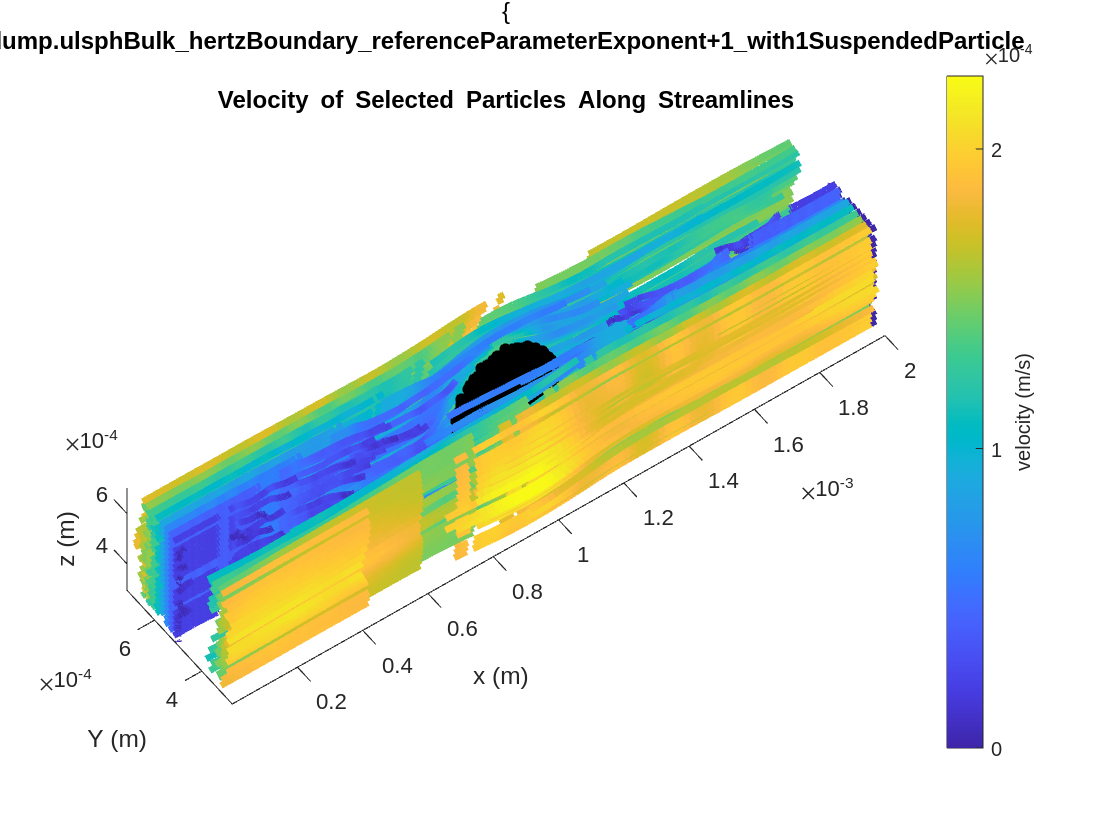

figure, hold on
col = parula(n);
warning off
for i=1:n
    jumps = [1;ntimesteps+1];
    for d=1:3
        jumps = unique([jumps;find(abs(diff(seltraj(:,d,i)))>boxdims(d)/2)+1]);
    end
    for j=1:length(jumps)-1
        u = jumps(j):jumps(j+1)-1;
        streamline = seltraj(u, :, i);
        color_line3(streamline(:, 1), streamline(:, 2), streamline(:, 3), selveloc_magnitude(u, i), 'linewidth', 3);
        % faster method but without streamline
        %plot3(traj(u,1,i),traj(u,2,i),traj(u,3,i),'-','linewidth',3,'color',col(i,:))
    end
end
plot3D(solidxyz,'ko','markerfacecolor','k','markersize',5)
view(3), axis equal
title({'\rm{' strrep(dumpfile, '_', '\_') '}:' '\bf{Velocity of Selected Particles Along Streamlines}'}, 'Interpreter', 'tex')
xlabel('x (m)'), ylabel('Y (m)'), zlabel('z (m)')
hc = colorbar; hc.Label.String = 'velocity (m/s)';
view([-35.851023 51.372457])

Summary: Step 15 combines numerical data processing (Lagrangian description) with visualization techniques to create a graphical representation of the selected particles' movement (trajectories matching streamlines at the steady state). This plot can be an essential tool for understanding and analyzing the turbulence deveopping in the wake flow.